**Ridge Regression** 

In this notebook, we will analyze how a ridges regression model performs on top of the already selected features. 

% country to consider for the analysis
country='china';

data = select_and_normalize(country,false);
tr = data.tr;
te = data.te;
y_tr = data.y_tr;
y_te = data.y_te;
col_names = data.col_names;
% we saw earlier that the best set of features for Taiwan consist of the following expansion.
if strcmp('taiwan',country)
    [tr,col_names_exp] = expand(tr,2,true,false,col_names);
    [te,~]             = expand(te,2,true,false,col_names);
    % result of the features selection performed on top of the expansion    
    cols = [1,2,3,5,6,7,10];
    tr = tr(:,cols);
    te = te(:,cols); 
    col_names = col_names_exp(cols);
end

**Hyperparameter optimization **

Ridge regression models depend on the parameter lambda. In this section, we try to find the optimal value for this parameter. We do so by looping over a logarithm range of values for lambda and look at the R2 scores produced on a test set. Note that we also include the value 0 in the range.

scores = [] ;
best_score  = -100;
best_lambda = 0 ;
for lambda=[0,logspace(-2,3,200)]
    model = ols(tr,y_tr,'ridge',lambda);
    beta = model.beta;
    test_score = test_model(beta,te,y_te);
    R2 = test_score.R2;
    scores = [scores,R2];
    % save best lambda and best score
    if R2 > best_score
        best_score = R2;
        best_lambda = lambda;
    end
end
best_lambda

best_lambda = 1.4481

best_score

best_score = -0.2206

**Evolution of the score**

Here we plot the obtain values for R2 scores against values of lambda

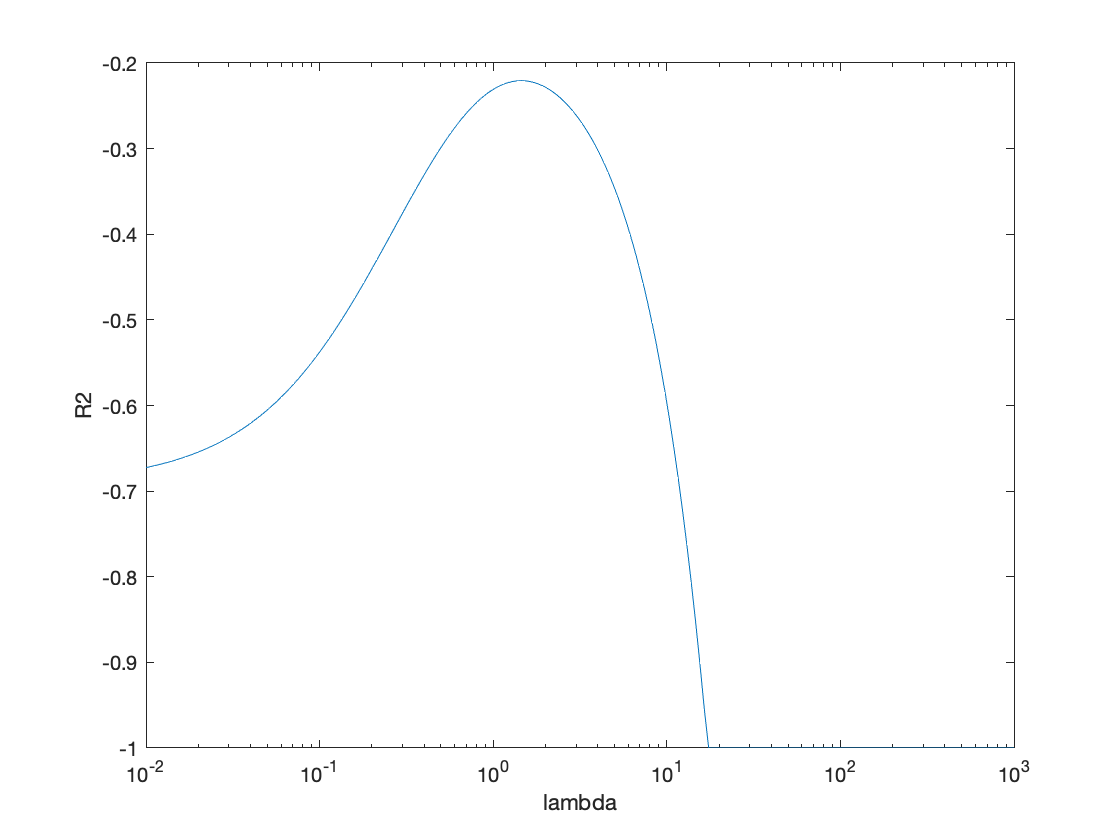

figure
semilogx([0,logspace(-2,3,200)],max(scores,-1))
ylabel({'R2'});
xlabel({'lambda'});